# Instituto Tecnológico de Aeronaútica

### Aluno: Eduardo Bezerra Robalinho Dantas da Gama;

### Professor: Dr. Francisco Alex Correia Monteiro

Problema da curva:

n=3000;
x=rand_ger(n,0,2);

Função dentro da integral

f=@(x) (1/sqrt(2*pi))*exp(-1/(2*x^2))/(x^2);

Vetor para receber o resultado das operações:

y=zeros(n,1);
for i=1:n
    y(i,1)=f(x(i,1));
end

Cálculo do valor da integral

integral=(2-0)*mean(y);

Print dos gráficos:

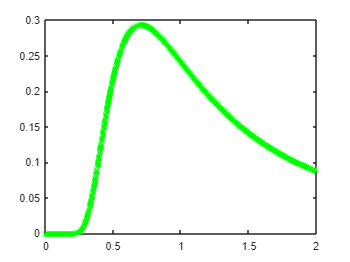

plot(x,y,'g*')

O método de monte carlo consiste em:

function Seq2=rand_ger(n,min,max)

Número de números gerados, metodo de D. H. Lehmer:

    m=2^32;
    a=3*17*131*20173;
    c=1;
    semente=0;

For:

    x=zeros(1,n);
    x(1,1)=semente;
    for i=1:n
        x(1,i+1)=mod(a*x(1,i)+c,m);
    end
    Seq=x/m;
    Seq2=Seq(1:n);

Colocar a sequência entre 0 e 1:

    Seq2=(min+(max-min)*Seq2)';
end